# Problem 1

## (a).


$$A = \pmatrix{ -2 & 11 \cr -10 & 5}$$


Consider $AA^T = \pmatrix{125 & 75 \cr 75 & 125}$.

The eigenvalues of $AA^T$ are 50 and 200 with eigenvectors $\pmatrix{-0.7071 \cr 0.7071}$ and $\pmatrix{0.7071 \cr 0.7071}$ respectively.

From this, we know that $\sigma_1 = \sqrt{200}, \sigma_2 = \sqrt{50}$ with left singular vectors $\pmatrix{0.7071 \cr 0.7071}$ and $\pmatrix{-0.7071 \cr 0.7071}$ respectively. 

So $U = \pmatrix{0.7071 & -0.7071 \cr 0.7071 & 0.7071}$ and $\Sigma = \pmatrix{\sqrt{200} & 0 \cr 0 & \sqrt{50}}$.

Consider $A^TA = \pmatrix{104 & -72 \cr -72 & 146}$.

Then, the eigenvalues of $A^TA$ are  50 and 200 with eigenvectors $\pmatrix{-0.8 \cr -0.6}$ and $\pmatrix{-0.6 \cr 0.8}$ respectively.

Thus, $V = \pmatrix{-0.6 & -0.8 \cr 0.8 & -0.6}$.

Therefore, $A = U \Sigma V^T = \pmatrix{0.7071 & -0.7071 \cr 0.7071 & 0.7071}\pmatrix{\sqrt{200} & 0 \cr 0 & \sqrt{50}}\pmatrix{-0.6 & 0.8 \cr -0.8 & -0.6}$.

## (B)


$$||A||_2 = \sigma_1 = \sqrt{200}$$



$$||A||_F = \sqrt{\sigma_1^2 + \sigma_2^2} = \sqrt{200 + 50} = \sqrt{250}$$


## (C)

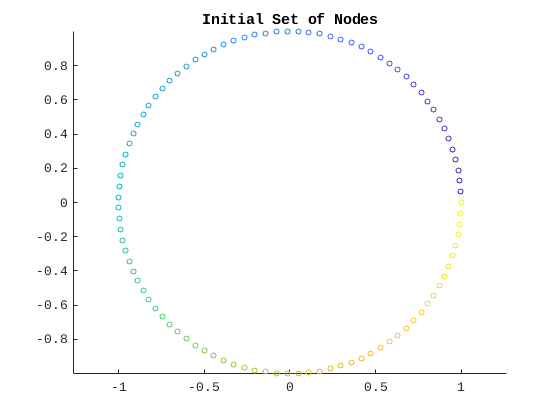

A = [-2, 11; -10, 5];
[U,S,V] = svd(A,0);

% Populate unit circle
N = 100;
theta = linspace(0,2*pi,N);
circ = [cos(theta); sin(theta)];

figure()
scatter(circ(1,:),circ(2,:),15,theta)
title('Initial Set of Nodes')
axis equal

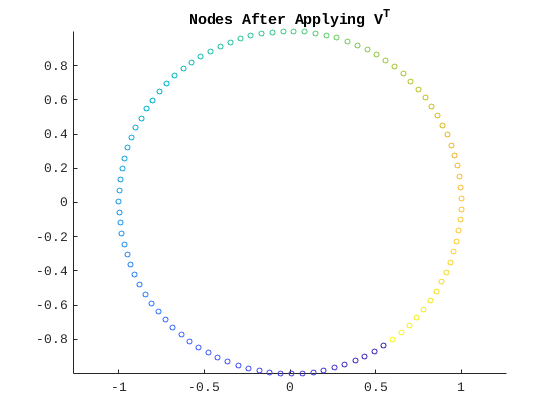


circ = V'*circ;
scatter(circ(1,:),circ(2,:),15,theta)
title('Nodes After Applying V^T')
axis equal

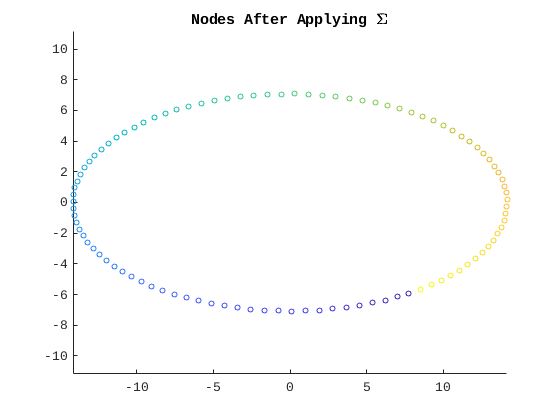


circ = S*circ;
scatter(circ(1,:),circ(2,:),15,theta)
title('Nodes After Applying \Sigma')
axis equal

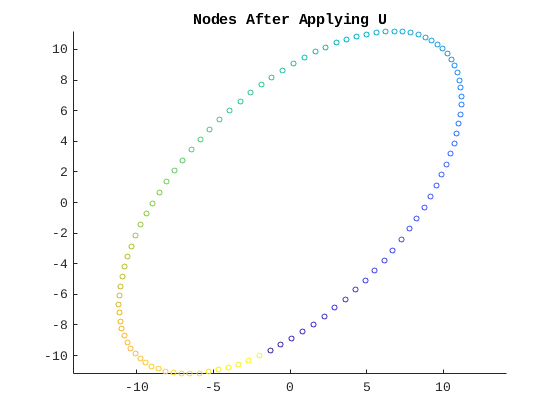


circ = U*circ;
scatter(circ(1,:),circ(2,:),15,theta)
title('Nodes After Applying U')
axis equal

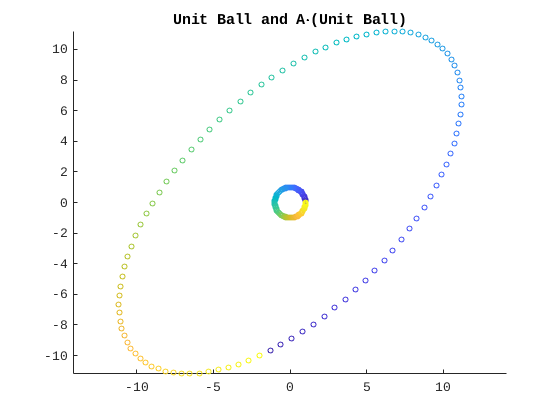

circ = [cos(theta); sin(theta)];
scatter(circ(1,:),circ(2,:),15,theta);
hold on
circ = A*circ;
scatter(circ(1,:),circ(2,:),15,theta)
title('Unit Ball and A\cdot(Unit Ball)')
axis equal

From all of the different plots, we can see that $V^T$ causes a rotation of our space, $\Sigma$ scales our space, and then $U$ rotates our space again. In the final plot, we can see the result of $A$ acting on the unit ball. As expected, $A$ combines each of the actions of $U,\Sigma,$ and $V^T$ on the unit ball! Note that the major and minor axis of the final ellipse are given by the singular values. This is due to the singular values in $\Sigma$ scale the standard basis by the singular values.

## (D)

lambda = eig(A)

lambda =    1.5000 + 9.8869i
   1.5000 - 9.8869i


The eigenvalues of $A$ are given by $\lambda \approx 1.5 \pm 9.8869 i$.

abs(det(A) - lambda(1)*lambda(2))

ans = 1.4211e-14

From this, we can see that $\det (A) = \lambda_1 \lambda_2$.

abs(abs(det(A)) - sqrt(200)*sqrt(50))

ans = 1.4211e-14

As expected, $|\det (A)| = \sigma_1 \sigma_2$.

## (E)

area = $\pi \sigma_1 \sigma_2 = \pi\sqrt{200}\sqrt{50} = 100\pi$

# Problem 2

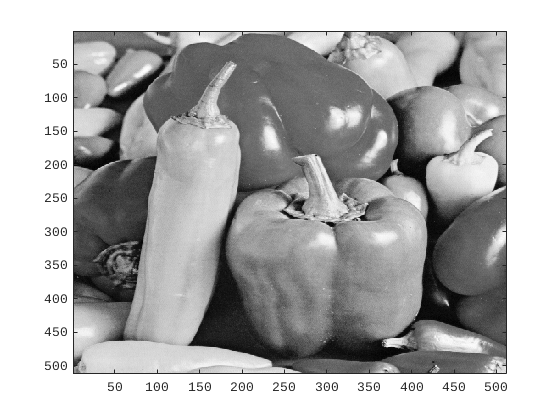

A = double(imread('Project6/peppers.png'));

figure()
imagesc(A)
colormap gray

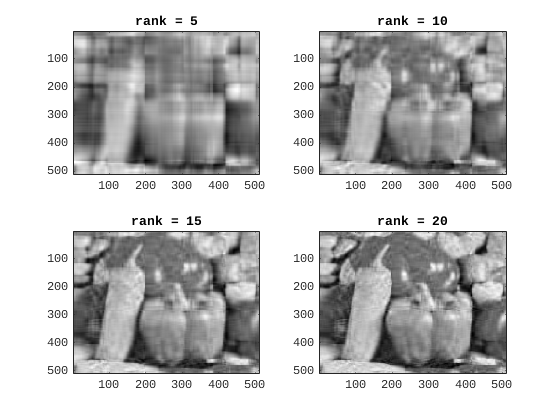

[U,S,V] = svd(A);
for i = 1:4
    subplot(2,2,i)
    k = 5*i;
    Ak = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    imagesc(Ak)
    colormap gray
    title(sprintf('rank = %d', k))
end

As expected, the plots show that as we increase the rank, the quality of the image increases towards the original quality of the image. The quality increase is due to the higher rank keeping more of the image data. When the rank is lower, we are only keeping the largest few singular values which only house the main information of the image. The largest singular values make up the large features of the image but they don't account for the intricate details. So, when we include more of the singular values, we recover some of those fine details.

# Problem 3

## (a) done

## (b) done

## (c)

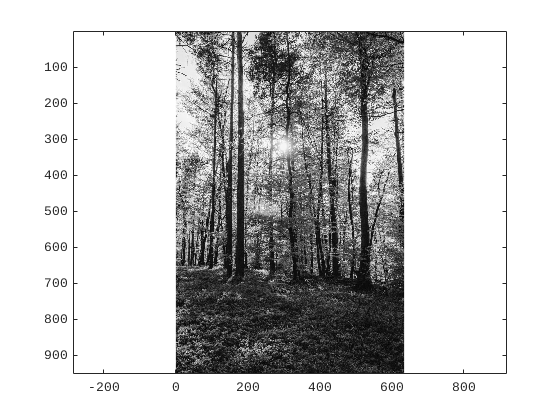

format long
A = imread('Project6/forests.jpg');
A = double(rgb2gray(A));

figure()
imagesc(A)
axis equal
colormap gray

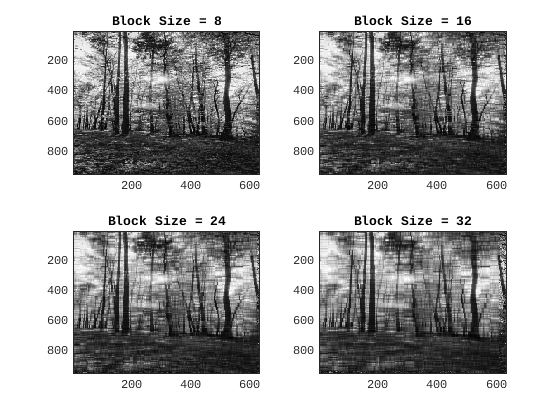

Ratio with blocksize 

8 = 0.262838


Ratio with blocksize 16 = 0.125939


Ratio with blocksize 24 = 0.082407


Ratio with blocksize 32 = 0.059401


figure()
bSize = [8,16,24,32];
for i = 1:4
    subplot(2,2,i)
    [compressedA, ratio] = svdcompress(A,bSize(i), 0.5);
    imagesc(compressedA, [0,255])
    fprintf('Ratio with blocksize %d = %f\n', bSize(i), ratio)
    colormap gray
    title(sprintf('Block Size = %d', bSize(i)))
end

From the different plots, we can see that as we increase the blocksize, the compression increases. This makes sense because a larger blocksize means we can use less singular values to represent more pixels. But, as a side effect of the increased compression, we also lose more resolution in our image. This is also explained by the decrease in the number of singular values that we are using to resolve the image. So, on the other end, if you want to increase the resolution, you should use smaller block sizes so you can recover the fine details easier.

## (d)

format long
A = imread('Project6/forests.jpg');
A = double(rgb2gray(A));

figure()
imagesc(A)
axis equal
colormap gray

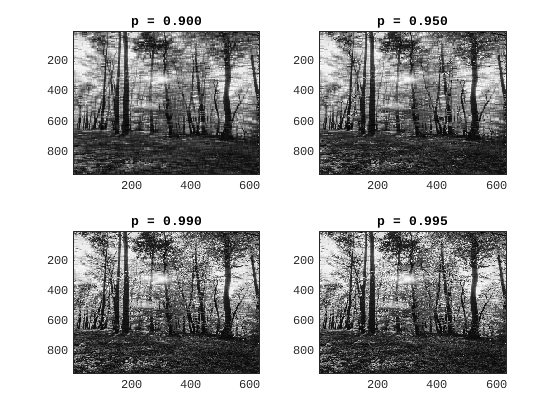

Ratio with p = 

0.900: = 0.131796


Ratio with p = 0.950: = 0.199828


Ratio with p = 0.990: = 0.567931


Ratio with p = 0.995: = 0.741438



figure()
p = [0.9,0.95,0.99,0.995];
for i = 1:4
    subplot(2,2,i)
    [compressedA, ratio] = svdcompress(A,16, p(i));
    imagesc(compressedA, [0,255])
    fprintf('Ratio with p = %.3f: = %f\n', p(i), ratio)
    colormap gray
    title(sprintf('p = %.3f', p(i)))
end

In contrast to the blocksize, as we increase the $p$ value, we are decreasing the compression of our image. This is because as $p$ increases, we keep more and more of our singular values (to maintain more of the total energy in our image). Thus as $p$ increases, the quality of the image increases at the cost of less compresssion.

function k = cutoff(sigma,p)
    n = length(sigma);
    k = 1;
    for i = 1:n
        if sum(sigma(1:i).^2)/sum(sigma .^ 2) >= p^2
            k = i;
            break;
        end
    end
end

function [Z,ratio] = svdcompress(X,b,p)
    Z = X;
    ratio = 0;
    
    for i = 1:size(X,1)/b
        for j = 1:size(X,2)/b
            % Get working image block
            Ak = X((i-1)*b+1:(i)*b,(j-1)*b+1:(j)*b);
            
            % Compute SVD of image block
            [U,S,V] = svd(Ak);
            
            % Store singular values
            sigma = diag(S);
            
            % compute rank to compress to
            k = cutoff(sigma,p);
            
            % Check if the svd is more compressed than the original image
            if k < b/2
                Z((i-1)*b+1:(i)*b,(j-1)*b+1:(j)*b) = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
                ratio = ratio + k*(2*b + 1);
            else
                ratio = ratio + b^2;
                continue;
            end
        end
    end
    ratio = ratio / (size(X,1)*size(X,2));
end